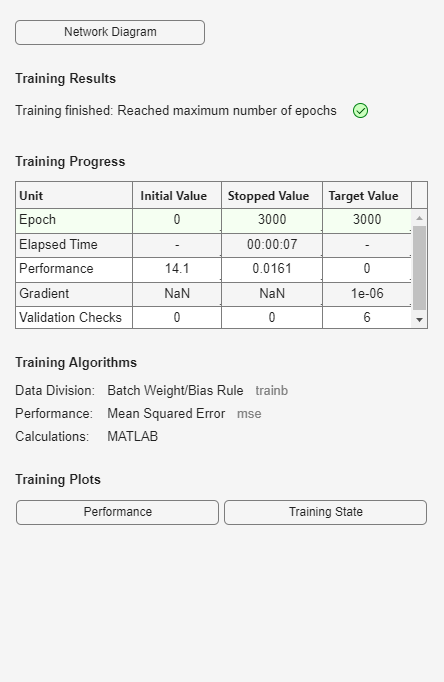

%ÈË¹¤Éñ¾­ÍøÂç
%ÏßÐÔÍøÂç¡ª¡ªµ¥ÊäÈë-µ¥Êä³ö£¨×î´ó»ýÑ©Éî¶ÈÓë¹à¸ÈÃæ»ýµÄ¹ØÏµ£©
x=[15.2 10.4 21.2 18.6 26.4 23.4 13.5 16.7 24.0 19.1]; 
y=[28.6 19.3 40.5 35.6 48.9 45.0 29.2 34.1 46.7 37.4];
P=x/10;                                     %ÊäÈëÊý¾ÝÈ«²¿³ýÒÔ10
T=y/10;                                     %Ä¿±êÊý¾ÝÈ«²¿³ýÒÔ10
net=newlin(minmax(P),1,0,0.01);             %¹¹½¨Ò»¸öµ¥Êä³öÏßÐÔÍøÂç
net.trainParam.epochs=3000;                 %Ö¸¶¨×î´ó¼ÆËã´ÎÊý
net=train(net,P,T);                         %ÍøÂçÑµÁ·

Y=sim(net,P);Y                              %·ÂÕæÓëÊýÖµÊä³ö

Y =     2.9913    2.1211    4.0790    3.6077    5.0218    4.4779    2.6831    3.2632    4.5867    3.6983


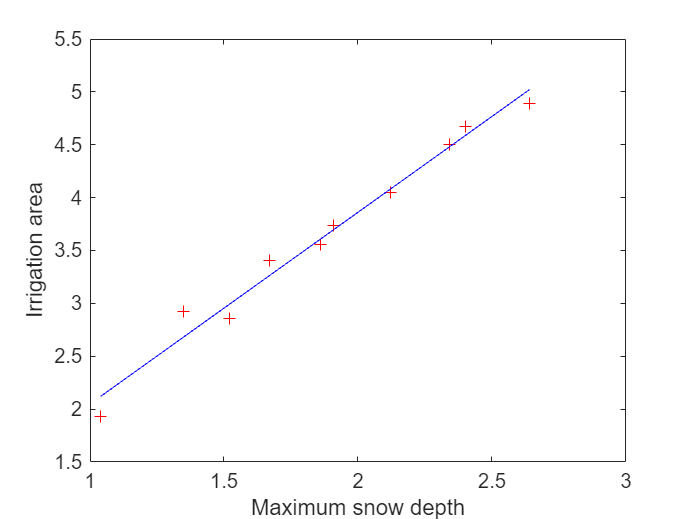

figure                                      %´´½¨ÁíÍâÒ»¸öÍ¼ÐÎ´°¿Ú
plot(P,T,'r+');                             %»æÖÆÉ¢µãÍ¼
xlabel('Maximum snow depth');               %ºáÖá±êÇ©£¨×î´ó»ýÑ©Éî¶È£©
ylabel('Irrigation area');                  %×ÝÖá±êÇ©£¨¹à¸ÈÃæ»ý£©
hold on                                     %±£³ÖÍ¼ÐÎ
plot(P,Y,'b-');                             %Ìí¼ÓÇ÷ÊÆÏß
hold off                                    %½áÊø»æÍ¼

w=net.iw{1,1}                               %¸ø³öÈ¨Êý/»Ø¹éÏµÊý

w = 1.8129

b=net.b{1}                                  %¸ø³öãÐÖµ/½Ø¾à

b = 0.2356

P_test=[27.5/10];                           %Ô¤²â
y=sim(net,P_test);                          %¼ÆËãÔ¤²â½á¹û
Y1981=y*10                                  %½«Ô¤²âÖµ×ª»»ÎªÔ­À´µÄÊýÖµµ¥Î»

Y1981 = 52.2118